## Flight Control Law Design and Application 

### Term Project Part I: Modelling

**Introduction**

This Matlab livescript is designed for the term project of the course 'Flight Control Law Design and Application'. It comprises all tasks to be done during the first half of Part I of the term project. The script is designed such that it will provide you with information, specific tasks, and the possibility to check your model and your progress by yourself. Further, this script will be used by us to verify your results at the end of Part I of the term project. 

The project folder you downloaded from StudIP comprises several models. All of the tasks in this script refer to the 'AircraftModel_LonMot.slx' model. The root level of the 'AircraftModel_LonMot.slx' model is shown below. It comprises several subsystems. These subsystems model the actuators and propuslion system of the aircraft, its aerodynamics and its longitudinal motion as a point mass. Further, external influence factors as wind and gravity are included. The model has two control inputs, the commanded elevator deflection and the thrust lever position. Several outputs can be used to investigate the aircraft.  

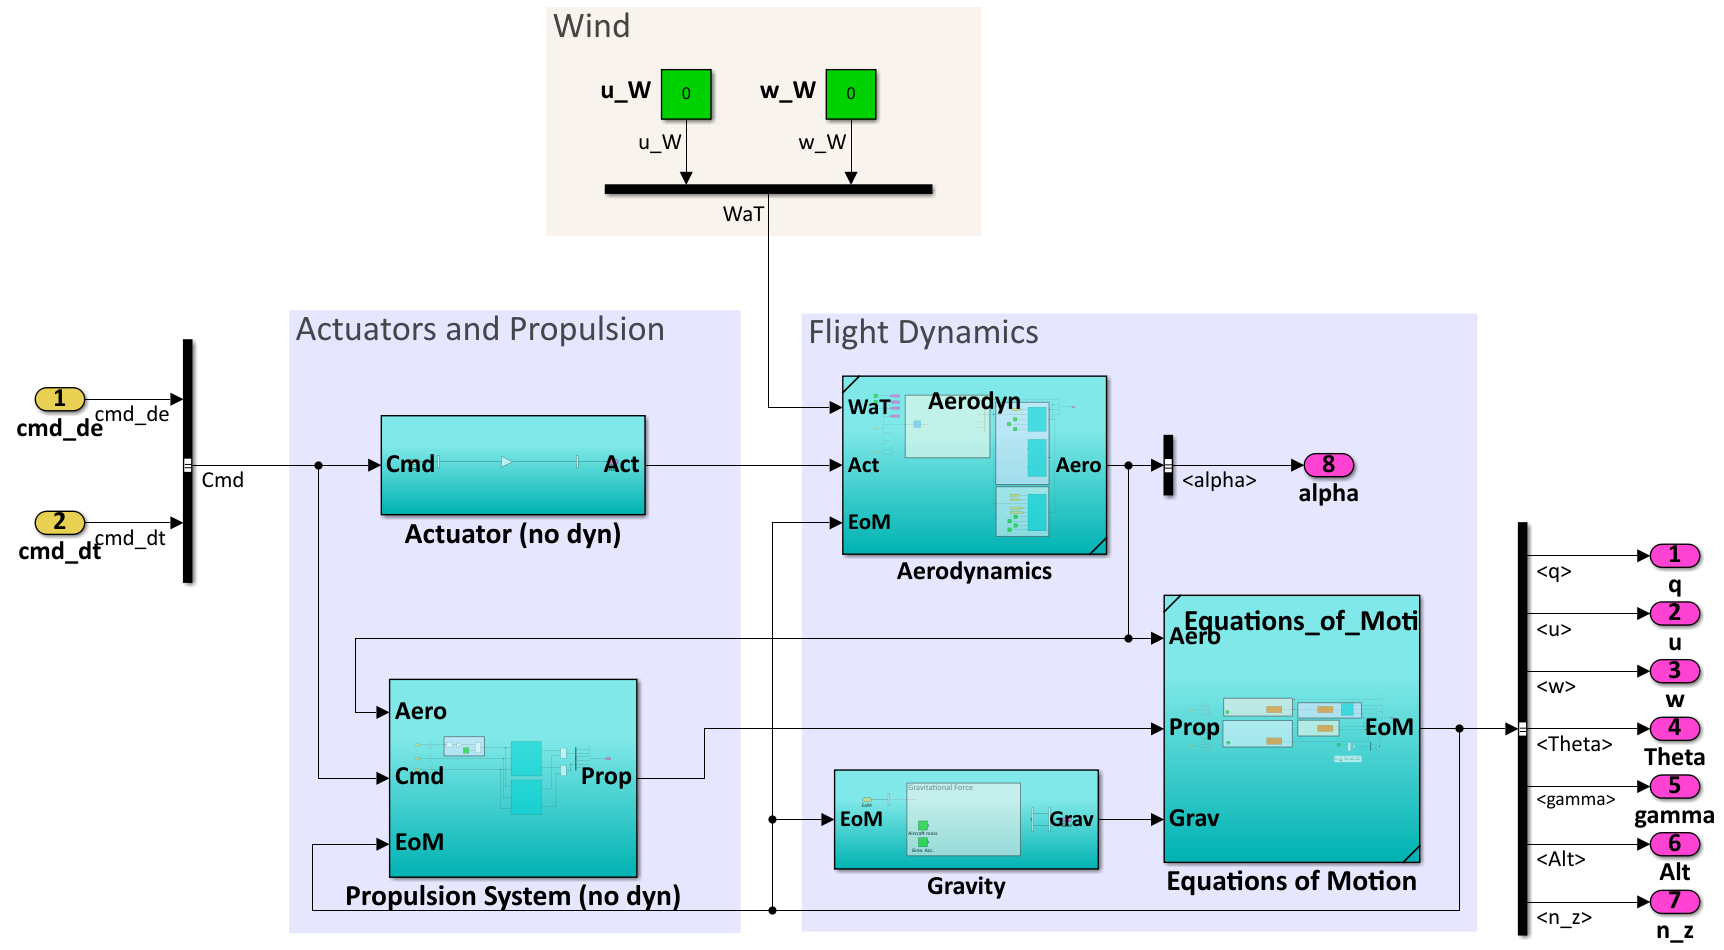

During the term project, you will augment and modify this model. You will further use it to derive mathmatical models used for controller design. Finally, the controllers and autopilots you design will be used to control the aircraft.

**Do's and Don'ts**

In order to use this livescript successfully, you have to fullfill the given **Tasks** (blockwise) in the given order. It is recommended to use the code sections one by one and to check your results before advancing. Otherwise, required results for subsequent parts might not be available. When running a code section, warnings and error messages will be displayed within this script analog to the usual output in the command window.

The 'AircraftModel_LonMot.slx' includes two so called 'Referenced Subsystems' (indicated by the triangles in the upper left and lower right corner, see the figure below). Any changes made within these subsystems will automatically propagate into the subsystem model of the same name in your project folder (e.g. 'Aerodyn.slx' in the '1_Checks' folder). This feature is intended and will be used during your checks. **But: changes must ****only be made within**** the 'AircraftModel_LonMot.slx' model!** That is, don't change the subsystem models in your project '1_Checks' folder or any other model.

You will be asked to modify embedded Matlab functions within the 'Referenced Subsystems' in the 'AircraftModel_LonMot.slx' model. When saving your changes, the dialog shown below might be displayed. In this case, click 'Save All' to automatically propagade your changes to the subsystem models in your project folder. 

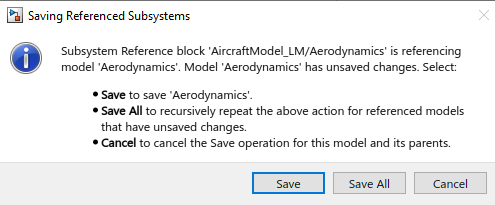

Start all your sessions by running the subsequent code section. Make sure that your current folder maintains this live script (see the picture below).

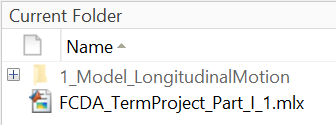

This code will run the 'AircraftParameters_LonMot.m' script and load several variables, structs, etc. into your Matlab workspace. Provided this, the 'AircraftModel_LonMot.slx' model is executable. Check the comments within the 'AircraftParameters_LonMot.m' script for further details on the variables, etc.. If not instructed otherwise, do not change the 'AircraftParameters_LonMot.m' script.

**Task 1: **load all required variables, structs, etc. into your Matlab workspace

- to do so, run this section (keyboard short cut: cntr + enter)

clear
clc
addpath('1_Model_LongitudinalMotion')
addpath('1_Model_LongitudinalMotion\1_Checks\')
run("AircraftParameters_LonMot.m"); 

**Equations of Motion**

The 'Equations of Motion' subsystem simulates the aircraft's motion within its $x_\text{f}$/$z_\text{f}$ plane. The subsystem comprises the equilibrium of forces and moments acting on the aircraft's center of gravity. The model already contains integrators including their parameterization (orange subsystems). They serve as focal points to construct the differential equations. Further, an embedded Matlab function ('Theta Calculation') is provided. Besides the translational and rotational velocities, the attitude, i.e. its pitch angle $\Theta$, the current altitude, the flight path angle $\gamma
$ and the load factors $n_x$ and $n_z$ are calculated. The inputs to the subsystem are the forces and moments due to aerodynamics, propulsion and gravity. 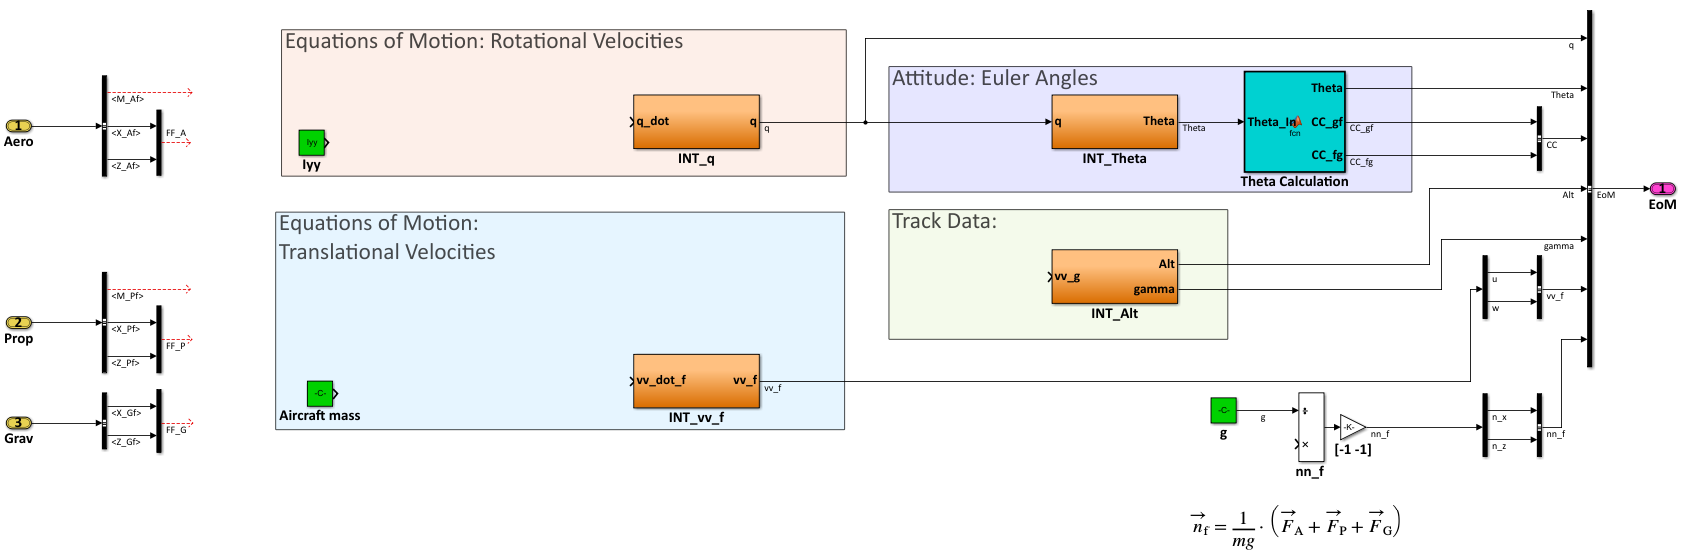

**Task 2:** Complete the 'Equations of Motion' subsystem

- open the 'AircraftModel_LonMot.slx' Simulink model (make changes only within this  model!)

- design the differential equation for the pitch rate 'q' using Simulink blocks

- design the differential equation for the translational velocities 'u' and 'w' using Simulink blocks

- design the load factor vector $\vec{n}_f$

- code the transformation matrizes $C^f_g$ and $C^g_f$ within the embedded Matlab function 'Theta Calculation'

- augment the 'INT_Alt' subsystem to calculate the aircraft's altitude and its flight path angle

Check your model using the subsequent figure. Your solution will be plotted in red, while a correct block outputs the black results. Correct your model if necessary. 

Note: You can choose between two output designs within this live script using the toolbar in the upper right corner of this 'Live Editor' window

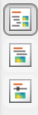

**Check: **Run this section to check your 'Equations of Motion' subsystem. It will be checked independent of any other subsystem! Note that the correct signals are not necessarily physically meaningfull, as they *only* test the equations of motion!

[out] = sim('Check_my_EoM');  % run simulation to compare your results

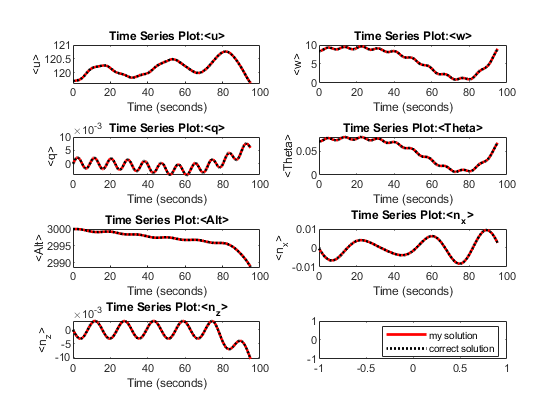

if exist('f100','var'), close (f100),  end
f100 = figure;
    subplot(4,2,1), plot(out.my_u,'r','linewidth',2), hold on, plot(out.check_u,'k:','linewidth',2), ...
    subplot(4,2,2), plot(out.my_w,'r','linewidth',2), hold on, plot(out.check_w,'k:','linewidth',2), ...
    subplot(4,2,3), plot(out.my_q,'r','linewidth',2), hold on, plot(out.check_q,'k:','linewidth',2), ...
    subplot(4,2,4), plot(out.my_Theta,'r','linewidth',2), hold on, plot(out.check_Theta,'k:','linewidth',2), ...
    subplot(4,2,5), plot(out.my_Alt,'r','linewidth',2), hold on, plot(out.check_Alt,'k:','linewidth',2), ...
    subplot(4,2,6), plot(out.my_nx,'r','linewidth',2), hold on, plot(out.check_nx,'k:','linewidth',2), ...
    subplot(4,2,7), plot(out.my_nz,'r','linewidth',2), hold on, plot(out.check_nz,'k:','linewidth',2), ...
    subplot(4,2,8), plot([0 0],[0 0],'r','linewidth',2), hold on, plot([0 0],[0 0],'k:','linewidth',2), legend('my solution','correct solution')

    clear out

**Wind**

To investigate disturbances to the aircraft, constant horizontal and vertical wind velocities can be simulated. The respective inputs are located on the root level of the aircraft model. Note that, for the time beeing, the horizontal wind remains in the $x_f/z_f$-plane only. 

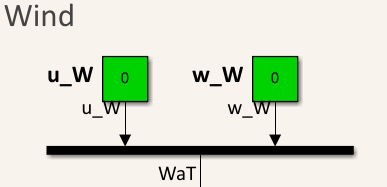

**Task 3:** Specify a bus object for the wind

- open the bus editor by typing 'buseditor' into your command window. 

- add a new bus object and name it 'WaT'  (Note: WaT stands for 'wind and turbulence'. We will not address turbulence in this term project.)

- define the following signals and maintain their order:  'u_W'  'w_W'

- give every entry (bus and signals) meaningfull description and both signals a unit

- open the 'AircraftModel_LonMot.slx' Simulink model

- exchange the 'mux' block collecting the signals 'u_W' and 'w_W' on the root level of the aircraft model with a 'Bus Creator' block from the Simulink library

- configure the 'Bus Creator' block: define the numer of inputs, choose the 'Output data type' to 'Bus: WaT'

- include the bus object 'WaT' into the 'BusObjects.mat' within your local project folder (overwrite the existing file)

**Check: **

display(WaT.Description); display(WaT.Elements(1).Name); display(WaT.Elements(2).Name);

  0×0 empty char array

u_W
w_W


display(WaT.Elements(1).Description); display(WaT.Elements(2).Description);

  0×0 empty char array

  0×0 empty char array



display(WaT.Elements(1).Unit); display(WaT.Elements(2).Unit)

  0×0 empty char array

  0×0 empty char array



**Gravity**

Gravity is acting on the center of gravity of the aircraft and shall be computed within the 'Gravity' subsystem shown below. 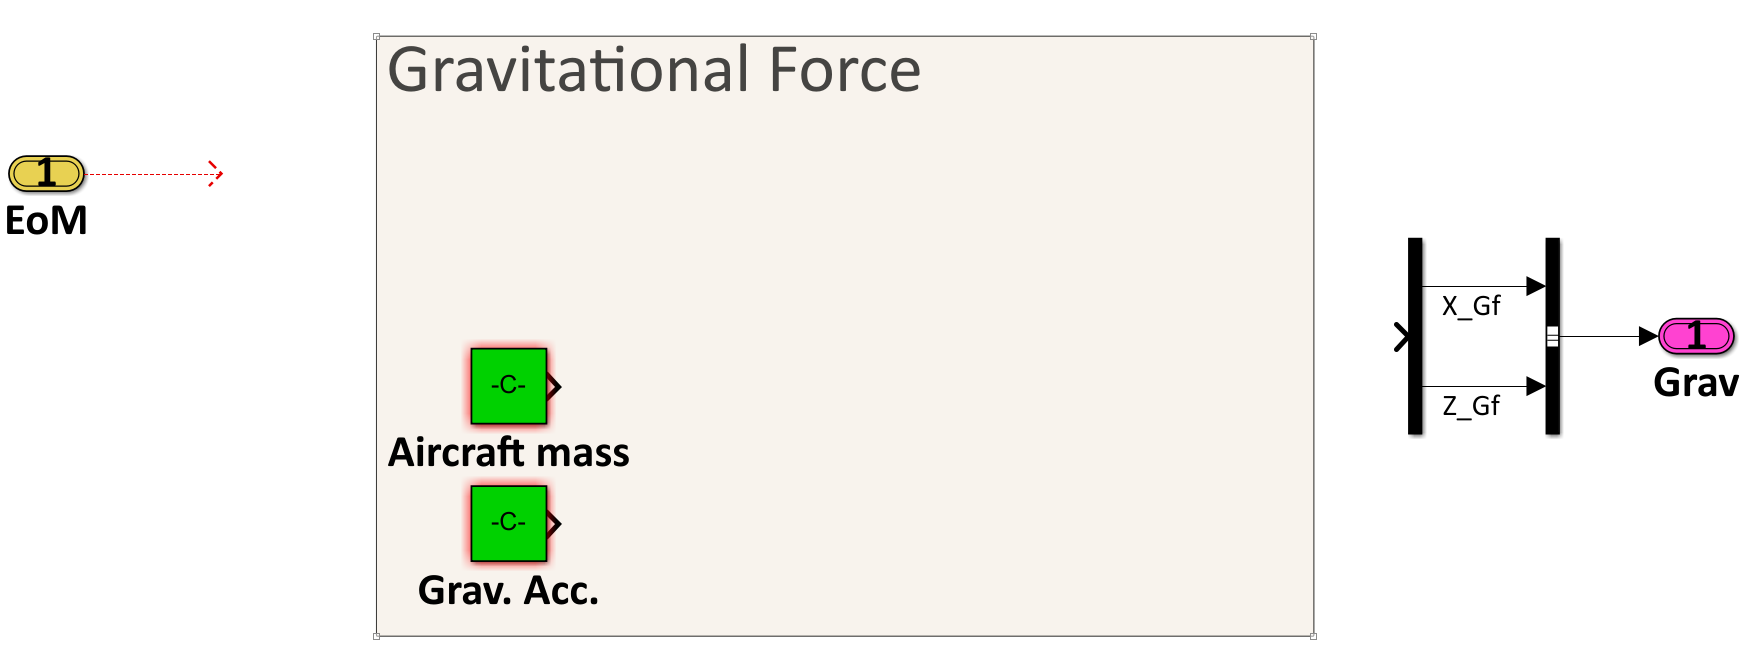

The gravitational force varies with the aircraft's mass and the acting gravitational acceleration. Within this project, we will assume a **constant mass** and **constant gravitational acceleration**. Note that both assumptions are simplifications of the reality, as any transport aircraft today burns fuel and thus loses weight over time. Moreover, the gravitational acceleration is variing with altitude and the aircraft's current location on earth.

**Task 4:** Model the gravitional force acting on the aircraft's center of gravity

- open the 'Gravity' subsystem within the 'AircraftModel_LonMot.slx' Simulink model

- include a 'Bus Selector' block and select the quantities required

- model the equtations to calculate the gravitational forces 'X_Gf' and 'Z_Gf'

**Aerodynamics**

The 'Aerodynamics' subsystem computes all aerodynamic forces and moments. It further comprises computations for basic air data, such as the dynamic pressure $$p_\text{dyn}$ or the angle of attack. The inputs to the subsystem are located on the left. Besides the outputs of the 'Equations of Motion' subsystem, the wind velocities (input 'WaT') and the deflections of the control surfaces (input 'Act') are required. The subsystem is devided into two major parts: While important air data will be computed in the left part, the aerodynamic forces and the pitching moment are calculated in the right half. The left part already includes a look up table to calculate the air density subject to the current altitude of the aircraft above mean sea level (MSL). Further, a signal bus 'AirData' is provided, including the signals to add.

In the right part of the subsystem, embedded Matlab functions are used to compute the forces and moments. 

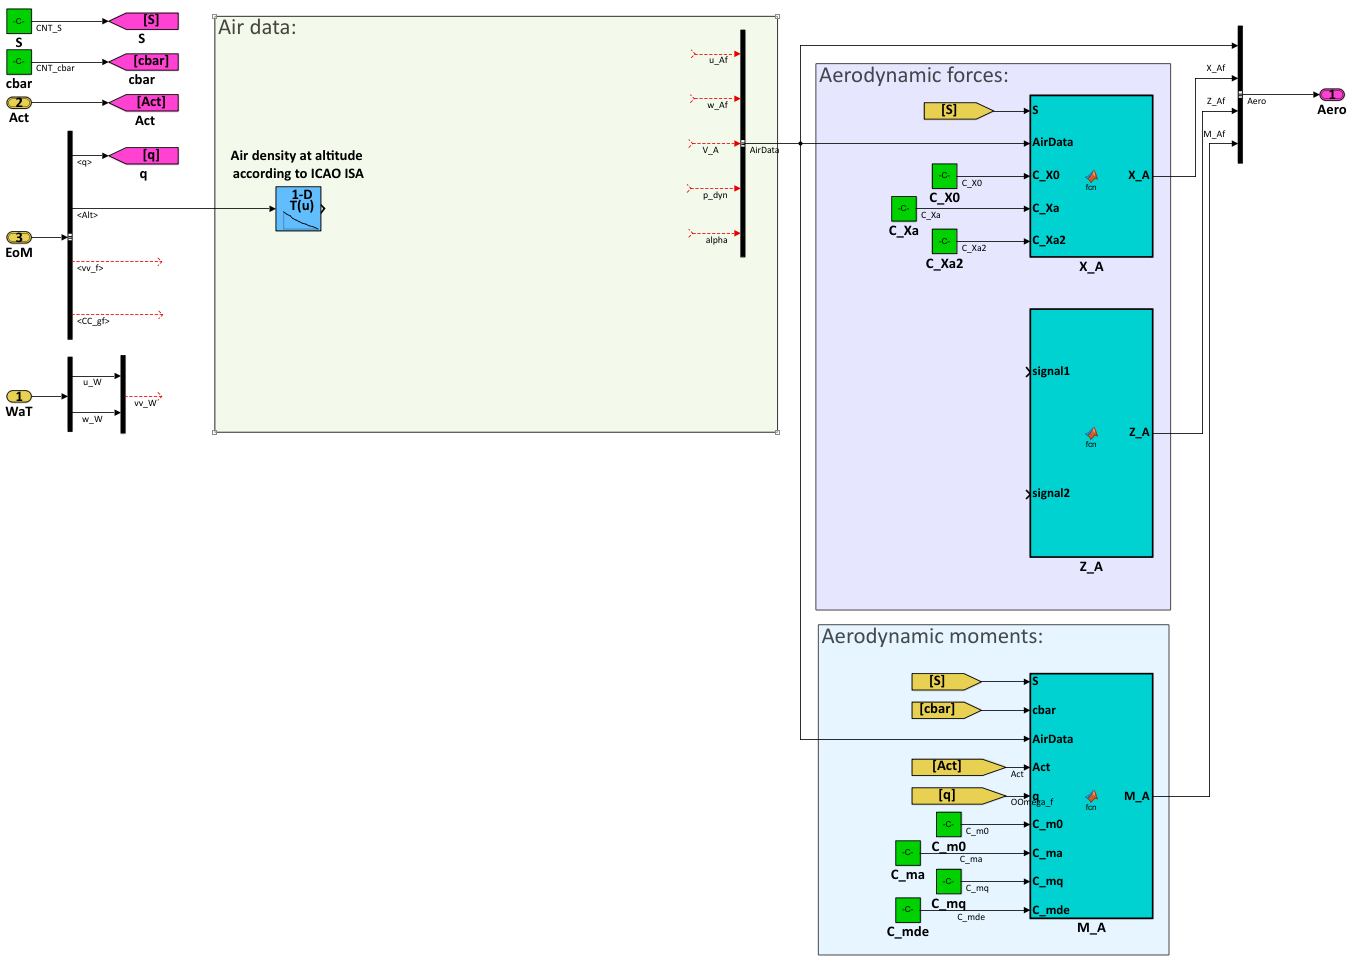

**Task 5: **Modify the 'Aerodynamics' submodel to use the new 'WaT' bus object 

- open the 'Aerodynamics' subsystem within the 'AircraftModel_LonMot.slx' Simulink model

- modify the 'WaT' input to the 'Aerodynamics' submodel

- link it to the newly specified bus object 'WaT': double click on the input block, then go to 'Signal Attributes/Data type'

- exchange the 'demux' block with a 'Bus Selector' block from the Simulink library and output the signals required

- save your model

**Task 6:** Complete the 'Aerodynamics' block

- use blocks from the Simulink library to compute the signals required by the 'AirData' signal bus

- augment the embedded Matlab functions for $X_{Af}$ and $M_{Af}$:  code the correct aerodynamic equations to compute the resp. force or moment, given the already provided inputs to the function

- design the embedded Matlab function for $Z_{Af}$: use the already provided ones as a guideline. Provide all necessary inputs to the block in order to compute $Z_{Af}$ correctly. (Note: more then two input signals are required!)

Check your 'Aerodynamics' subsystem using the subsequent figure. Your solution will be plotted in red. If your model is correct, your outputs will match the black signals. Correct your model if necessary.

**Check: **Run this section to check your 'Aerodynamics' subsystem. It will be checked independent of any other subsystem! Note that the correct signals are not necessarily physically meaningfull, as this function tests *only* the aerodynamics calculation!

load BusObjects_LonMot.mat; % (re-)load all bus objects required
[out] = sim('Check_my_Aerodynamics'); % run simulation to compare your results

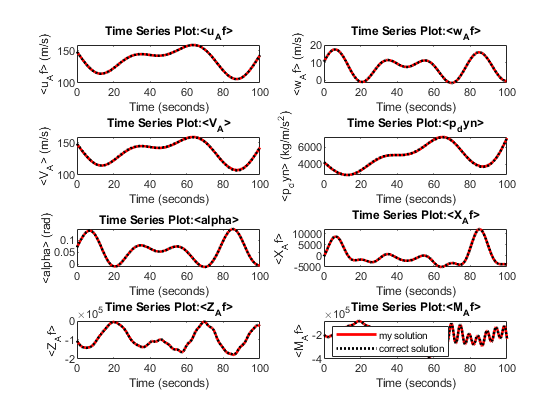

if exist('f110','var'), close (f110),  end
f110 = figure;
    subplot(4,2,1), plot(out.my_uAf,'r','linewidth',2), hold on, plot(out.check_uAf,'k:','linewidth',2), ...
    subplot(4,2,2), plot(out.my_wAf,'r','linewidth',2), hold on, plot(out.check_wAf,'k:','linewidth',2), ...
    subplot(4,2,3), plot(out.my_V_A,'r','linewidth',2), hold on, plot(out.check_V_A,'k:','linewidth',2), ...
    subplot(4,2,4), plot(out.my_p_dyn,'r','linewidth',2), hold on, plot(out.check_p_dyn,'k:','linewidth',2), ...
    subplot(4,2,5), plot(out.my_alpha,'r','linewidth',2), hold on, plot(out.check_alpha,'k:','linewidth',2), ...
    subplot(4,2,6), plot(out.my_X_Af,'r','linewidth',2), hold on, plot(out.check_X_Af,'k:','linewidth',2), ...
    subplot(4,2,7), plot(out.my_Z_Af,'r','linewidth',2), hold on, plot(out.check_Z_Af,'k:','linewidth',2), ...
    subplot(4,2,8), plot(out.my_M_Af,'r','linewidth',2), hold on, plot(out.check_M_Af,'k:','linewidth',2), legend('my solution','correct solution','location','south west')

    clear out

% end of file